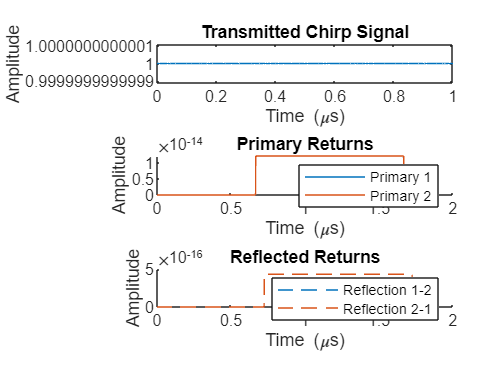

% Parameters
c = 3e8;                    % Speed of light (m/s)
f0 = 1e9;                   % Carrier frequency (Hz)
bandwidth = 1e6;            % Chirp bandwidth (Hz)
chirp_duration = 1e-6;      % Chirp duration (seconds)
sampling_rate = 1e9;        % Sampling rate (Hz)
t_chirp = 0:1/sampling_rate:chirp_duration;

% Target parameters (now with bearings)
object_distances = [100, 100];  % Same distance for ambiguity
object_velocities = [50, -30];  % Radial velocities in m/s (+ve away from radar)
object_bearings = [5, -5];      % Bearings in degrees
reflectivity = [0.8, 0.8];      % Matching reflectivity for ambiguity

% Antenna parameters
beamwidth = 10;             % Antenna beamwidth (degrees)
antenna_gain = @(theta) exp(-theta.^2/(2*(beamwidth/2)^2)); % Gaussian pattern

% Generate linear chirp signal
%chirp_signal = sin(2*pi*(f0*t_chirp + (bandwidth/(2*chirp_duration))*t_chirp.^2));
% Generate complex chirp signal
chirp_signal = exp(1i*2*pi*(f0*t_chirp + (bandwidth/(2*chirp_duration))*t_chirp.^2));


% Convert targets to Cartesian coordinates
angles_rad = deg2rad(object_bearings);
x = object_distances .* cos(angles_rad);
y = object_distances .* sin(angles_rad);

% Calculate inter-object distances
num_objects = length(object_distances);
d_ij = zeros(num_objects);
for i = 1:num_objects
    for j = 1:num_objects
        d_ij(i,j) = sqrt((x(i)-x(j))^2 + (y(i)-y(j))^2);
    end
end

% Time vector setup
max_delay = max(2*object_distances/c + ...                % Primary returns
              max(d_ij(:))/c + ...                        % Reflected paths
              chirp_duration) + ... % take the max of all these posibilities
              1/sampling_rate; % add an extra sample (for the math to work out)
time = 0:1/sampling_rate:max_delay;
radar_signal = zeros(size(time));

% Physical layer improvements
lambda = c/f0;
Pt = 1;  % Assume unit transmit power

% Simulate primary returns
primary_returns = zeros(num_objects, length(time));
for i = 1:num_objects
    R = object_distances(i);
    theta = object_bearings(i);
    
    % Radar equation components
    G = antenna_gain(theta);
    path_loss = (4*pi)^3 * R^4 / (lambda^2);
    Pr = (Pt * G^2 * reflectivity(i) * lambda^2) / path_loss;
    
    % Time delay calculation
    delay = 2*R/c;
    samples = round(delay*sampling_rate) + (1:length(chirp_signal));
    
    % Add to radar signal
    if max(samples) <= length(time)
        % adjust for doppler
        base_signal = apply_doppler_shift(chirp_signal, t_chirp, object_velocities(i), f0, c);
        primary_returns(i, samples) = Pr * base_signal;
        radar_signal(samples) = radar_signal(samples) + primary_returns(i,samples);
    end
end

% Simulate bistatic returns
reflected_returns = zeros(num_objects, num_objects, length(time));
for i = 1:num_objects
    for j = 1:num_objects
        if i == j, continue; end
        
        % Calculate total path: Radar->i->j->Radar
        total_distance = object_distances(i) + d_ij(i,j) + object_distances(j);
        theta_tx = object_bearings(i);
        theta_rx = object_bearings(j);
        
        % Radar equation components
        G_tx = antenna_gain(theta_tx);
        G_rx = antenna_gain(theta_rx);
        path_loss = (4*pi)^3 * total_distance^4 / (lambda^2);
        Pr = (Pt * G_tx * G_rx * reflectivity(i) * reflectivity(j) * lambda^2) / path_loss;
        
        % Time delay calculation
        delay = total_distance/c;
        samples = round(delay*sampling_rate) + (1:length(chirp_signal));
        
        % Add to radar signal
        if max(samples) <= length(time)
            % compute velocity and adjust for doplar
            combined_velocity = 0.5*(object_velocities(i) + object_velocities(j));
            base_signal = apply_doppler_shift(chirp_signal, t_chirp, combined_velocity, f0, c);
            reflected_returns(i,j,samples) = Pr * base_signal;
            radar_signal(samples) = radar_signal(samples) + squeeze(reflected_returns(i,j,samples))';
        end
    end
end

% Visualization

% plotting absolute value
%<>
figure;
subplot(3,1,1);
plot(t_chirp*1e6, abs(chirp_signal));
title('Transmitted Chirp Signal');
xlabel('Time (\mus)');
ylabel('Amplitude');

subplot(3,1,2);
hold on;
for i = 1:num_objects
    plot(time*1e6, abs(primary_returns(i,:)), 'DisplayName', sprintf('Primary %d',i));
end
title('Primary Returns');
xlabel('Time (\mus)');
ylabel('Amplitude');
legend;

subplot(3,1,3);
hold on;
for i = 1:num_objects
    for j = 1:num_objects
        if i ~= j
            plot(time*1e6, squeeze(abs(reflected_returns(i,j,:))), '--', ...
                 'DisplayName', sprintf('Reflection %d-%d',i,j));
        end
    end
end
title('Reflected Returns');
xlabel('Time (\mus)');
ylabel('Amplitude');
legend;

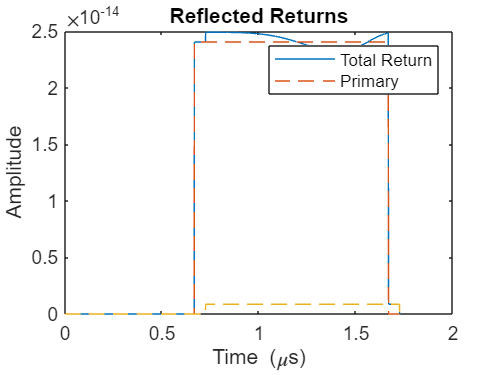


% continguation of abs val plotting

% now plot with total returns
figure;

%total returns
plot(time*1e6, abs(radar_signal), "DisplayName","Total Return")
title('Reflected Returns');
xlabel('Time (\mus)');
ylabel('Amplitude');

% primary returns
hold on;
plot(time*1e6, abs(squeeze(sum(primary_returns,1))'), '--', ...
    'DisplayName', sprintf('Primary'));
title('Reflected Returns');
xlabel('Time (\mus)');
ylabel('Amplitude');
legend;

% reflected returns
hold on;
plot(time*1e6, abs(squeeze(sum(reflected_returns,[1,2]))'), '--', ...
    'DisplayName', sprintf('Reflection'));
title('Reflected Returns');
xlabel('Time (\mus)');
ylabel('Amplitude');

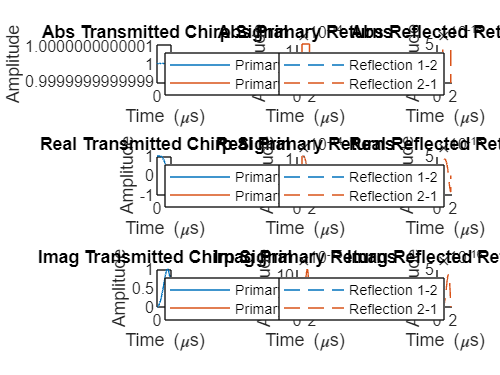

legend;

%</>
% end plotting absolute value





% plot all components
% <>

figure;
subplot(3,3,1);
plot(t_chirp*1e6, abs(chirp_signal));
title('Abs Transmitted Chirp Signal');
xlabel('Time (\mus)');
ylabel('Amplitude');

subplot(3,3,2);
hold on;
for i = 1:num_objects
    plot(time*1e6, abs(primary_returns(i,:)), 'DisplayName', sprintf('Primary %d',i));
end
title('Abs Primary Returns');
xlabel('Time (\mus)');
ylabel('Amplitude');
legend;

subplot(3,3,3);
hold on;
for i = 1:num_objects
    for j = 1:num_objects
        if i ~= j
            plot(time*1e6, squeeze(abs(reflected_returns(i,j,:))), '--', ...
                 'DisplayName', sprintf('Reflection %d-%d',i,j));
        end
    end
end
title('Abs Reflected Returns');
xlabel('Time (\mus)');
ylabel('Amplitude');
legend;

% now the real parts
subplot(3,3,4);
plot(t_chirp*1e6, real(chirp_signal));
title('Real Transmitted Chirp Signal');
xlabel('Time (\mus)');
ylabel('Amplitude');

subplot(3,3,5);
hold on;
for i = 1:num_objects
    plot(time*1e6, real(primary_returns(i,:)), 'DisplayName', sprintf('Primary %d',i));
end
title('Real Primary Returns');
xlabel('Time (\mus)');
ylabel('Amplitude');
legend;

subplot(3,3,6);
hold on;
for i = 1:num_objects
    for j = 1:num_objects
        if i ~= j
            plot(time*1e6, squeeze(real(reflected_returns(i,j,:))), '--', ...
                 'DisplayName', sprintf('Reflection %d-%d',i,j));
        end
    end
end
title('Real Reflected Returns');
xlabel('Time (\mus)');
ylabel('Amplitude');
legend;


% now the imaginary parts 
% now the real parts
subplot(3,3,7);
plot(t_chirp*1e6, imag(chirp_signal));
title('Imag Transmitted Chirp Signal');
xlabel('Time (\mus)');
ylabel('Amplitude');

subplot(3,3,8);
hold on;
for i = 1:num_objects
    plot(time*1e6, imag(primary_returns(i,:)), 'DisplayName', sprintf('Primary %d',i));
end
title('Imag Primary Returns');
xlabel('Time (\mus)');
ylabel('Amplitude');
legend;

subplot(3,3,9);
hold on;
for i = 1:num_objects
    for j = 1:num_objects
        if i ~= j
            plot(time*1e6, squeeze(imag(reflected_returns(i,j,:))), '--', ...
                 'DisplayName', sprintf('Reflection %d-%d',i,j));
        end
    end
end
title('Imag Reflected Returns');
xlabel('Time (\mus)');
ylabel('Amplitude');
legend;

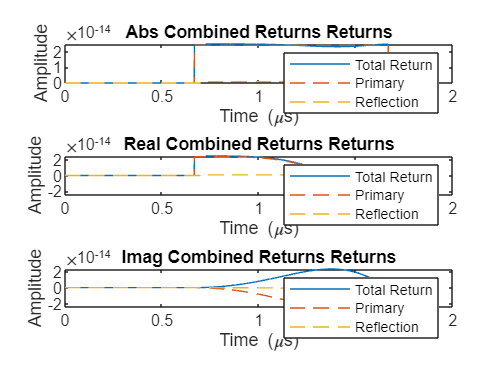


% continuation of all component ploting 

% total returns
% now plot with total returns
figure;

% abs val
subplot(3,1,1);

%total returns
plot(time*1e6, abs(radar_signal), "DisplayName","Total Return")
title('Abs Combined Returns Returns');
xlabel('Time (\mus)');
ylabel('Amplitude');

% primary returns
hold on;
plot(time*1e6, abs(squeeze(sum(primary_returns,1))'), '--', ...
    'DisplayName', sprintf('Primary'));

% reflected returns
hold on;
plot(time*1e6, abs(squeeze(sum(reflected_returns,[1,2]))'), '--', ...
    'DisplayName', sprintf('Reflection'));
legend;


% real val
subplot(3,1,2);

%total returns
plot(time*1e6, real(radar_signal), "DisplayName","Total Return")
title('Real Combined Returns Returns');
xlabel('Time (\mus)');
ylabel('Amplitude');

% primary returns
hold on;
plot(time*1e6, real(squeeze(sum(primary_returns,1))'), '--', ...
    'DisplayName', sprintf('Primary'));

% reflected returns
hold on;
plot(time*1e6, real(squeeze(sum(reflected_returns,[1,2]))'), '--', ...
    'DisplayName', sprintf('Reflection'));
legend;

% imag val
subplot(3,1,3);

%total returns
plot(time*1e6, imag(radar_signal), "DisplayName","Total Return")
title('Imag Combined Returns Returns');
xlabel('Time (\mus)');
ylabel('Amplitude');

% primary returns
hold on;
plot(time*1e6, imag(squeeze(sum(primary_returns,1))'), '--', ...
    'DisplayName', sprintf('Primary'));

% reflected returns
hold on;
plot(time*1e6, imag(squeeze(sum(reflected_returns,[1,2]))'), '--', ...
    'DisplayName', sprintf('Reflection'));
legend;



% <\>
% end plot all components


figure

% Calculate temporal resolution
delta_t = 1/bandwidth;
range_resolution = c*delta_t/2;
fprintf('Theoretical range resolution: %.2f meters\n', range_resolution);

Theoretical range resolution: 150.00 meters



figure;
plot_psd(sampling_rate, total_signal)

Unrecognized function or variable 'total_signal'.


figure;
plot_psd(sampling_rate, chirp_signal)

spectrogram(total_signal, 128, 120,128, sampling_rate, "yaxis")
spectrogram(total_signal, 2^7, 2^7-4,2^8, sampling_rate, "yaxis")
%spectrogram(total_signal, 2^7, 2^7-2e5,2^8, sampling_rate, "yaxis") % poor time accuracy
spectrogram(total_signal, 2^7, 2^7-4,2^12, sampling_rate, "yaxis") % poor time accuracy

function shifted_signal = apply_doppler_shift(signal, t, velocity, f0, c)
    % Apply Doppler shift to a signal based on radial velocity
    % Inputs:
    %   signal - Original signal vector
    %   t      - Time vector for the signal
    %   velocity - Radial velocity (m/s, positive = moving away)
    %   f0     - Carrier frequency (Hz)
    %   c      - Speed of light (m/s)
    
    % Calculate Doppler scaling factor
    alpha = 1 + 2*velocity/c;  % Time scaling factor
    
    % Apply time scaling and frequency shift
    t_scaled = t * alpha;
    phase_shift = 2*pi*f0*(1 - alpha)*t;
    shifted_signal = interp1(t, signal, t_scaled, 'linear', 0);
    shifted_signal = shifted_signal .* exp(1i*phase_shift);
end


function plot_psd(sampling_rate, signal)
    % Compute the Power Spectral Density (PSD) of a signal and plot it
    % Inputs:
    %   sampling_rate - sampling frequency in Hz
    %   signal        - input time series data
    
    Fs = sampling_rate;
    N = length(signal);
    
    % Apply Hamming window to reduce spectral leakage
    window = hamming(N);
    signal_windowed = signal .* window;
    signal_windowed = signal;
    
    % Compute FFT
    Y = fft(signal_windowed);
    
    % Calculate PSD (|FFT|^2 normalized appropriately)
    Pyy = (abs(Y).^2) / (Fs * sum(window.^2));
    
    % Take single-sided spectrum and handle even/odd N
    num_unique_points = ceil(N/2) + 1;
    Pyy = Pyy(1:num_unique_points);
    
    % Double the power for non-DC/non-Nyquist components
    if mod(N, 2) == 0
        Pyy(2:end-1) = 2 * Pyy(2:end-1);  % Even N (Nyquist exists)
    else
        Pyy(2:end) = 2 * Pyy(2:end);      % Odd N (no Nyquist)
    end
    
    % Create frequency axis
    f = (0:num_unique_points-1) * Fs / N;
    
    % Plot PSD in dB/Hz
    plot(f, 10*log10(Pyy));
    xlabel('Frequency (Hz)');
    ylabel('Power/Frequency (dB/Hz)');
    title('Power Spectral Density');
    grid on;
end


